# Group Project Part 4: Fourier Analysis

## Run SIR Model Using 1 Day Period

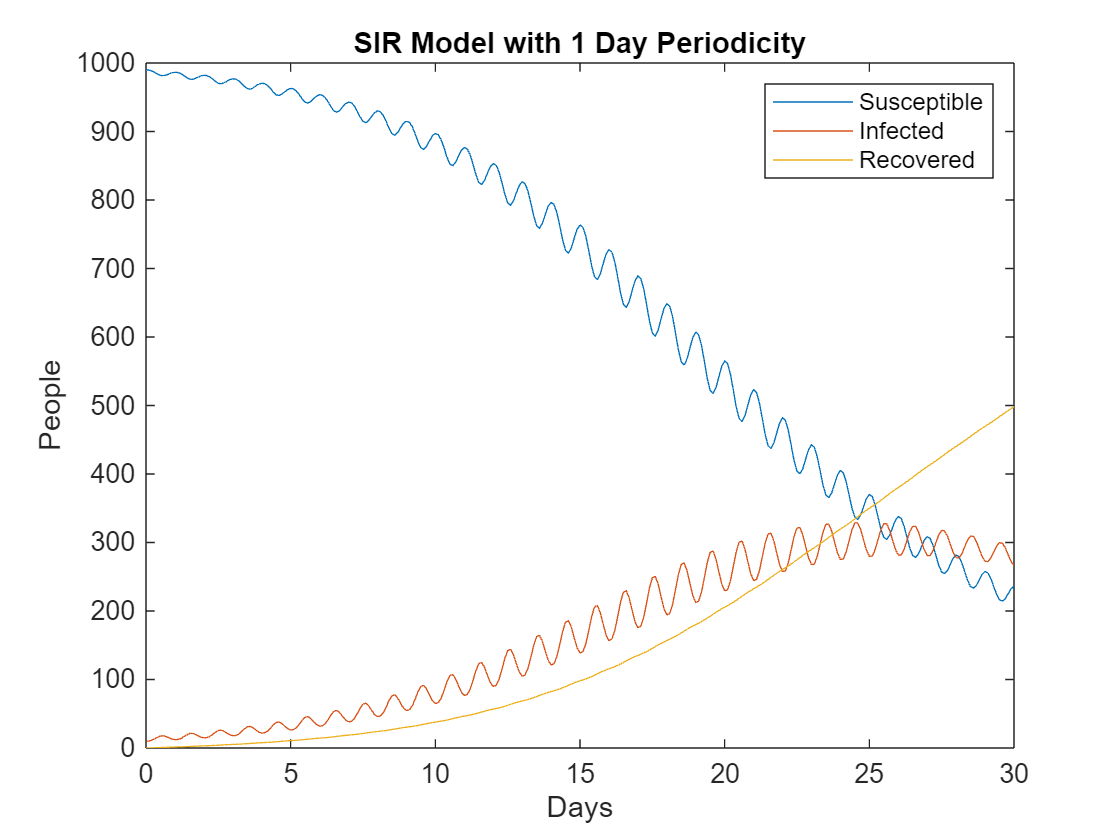

[t,S,I,R]=SIR(0.3,5,2*pi); %See function below
figure()
plot(t,S,t,I,t,R);
legend('Susceptible','Infected','Recovered')
title('SIR Model with 1 Day Periodicity')
xlabel('Days')
ylabel('People')

The graph shows periodic fluctuations in the numbers of susceptible and infected people, however the numbers of recovered people do not show as strong of fluctuations, but they are still there and can be seen if zoomed in. The trends of all three signals remains nearly the same as before, but there are oscillations around the standard values. 

## Perform fft for All Variables

fft(S);
fft(I);
fft(R); 

## Plot Spectrum Graph

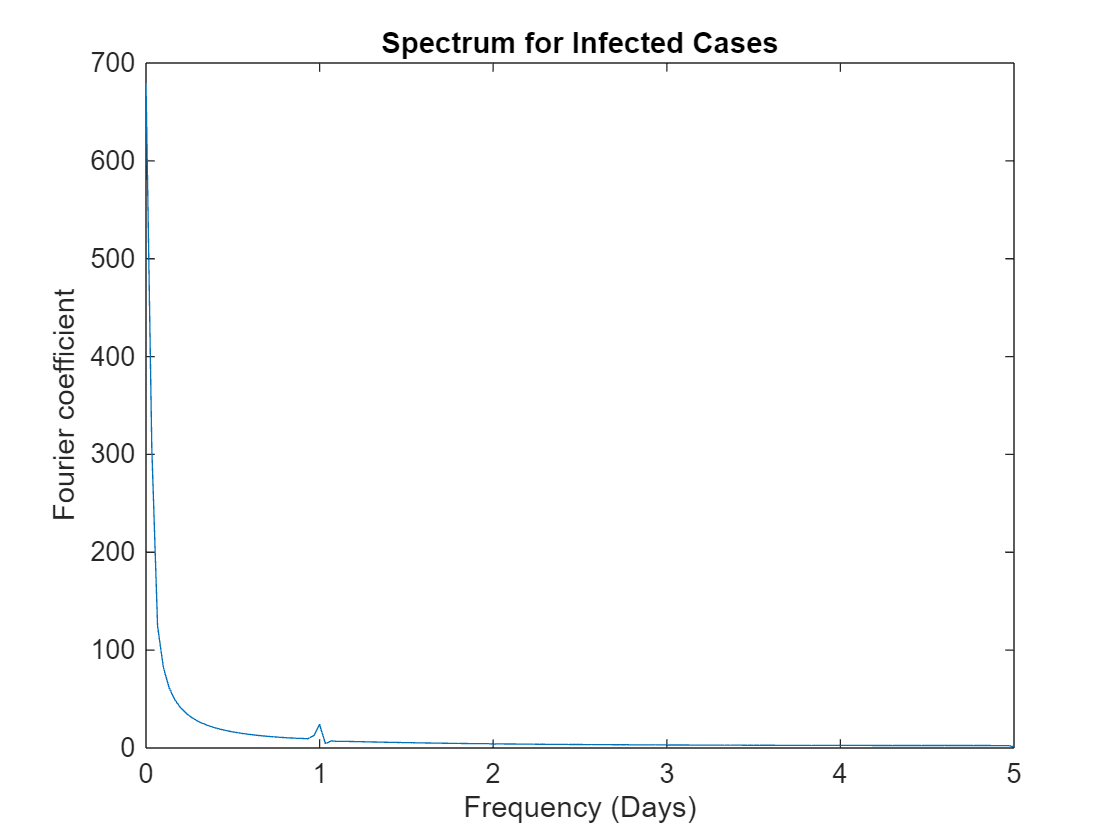

% Define frequency range
N=length(t)-1;
f = 1/30*(0:length(t)/2);
% Calculate spectrum
spectrum=fft(S);
P2 = abs(spectrum/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1)
title('Spectrum for Infected Cases')
xlabel('Frequency (Days)')
ylabel('Fourier coefficient')

A peak can be seen at a frequency of 0 and 1 day. The 0 day peak is mostly irrelevant as it only shows that there is still a component that does not fluctuate. The 1 day component shows that more people get infected once per day. This makes sense as most people tend to go to work once per day, so they would be more exposed and therefore more likely to become infected during this time. 

## Run SIR Model Using 3 Day Period

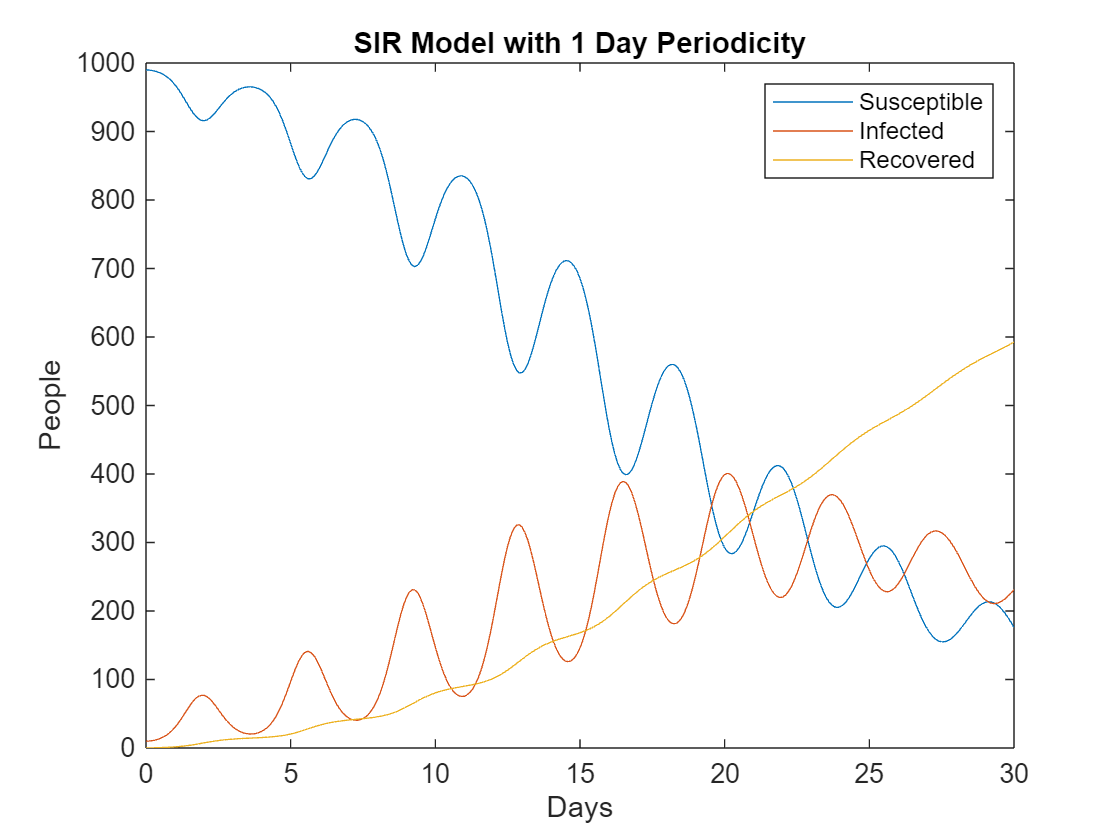

[t1,S1,I1,R1]=SIR(0.3,5,2*pi*100/365); %See function below
figure()
plot(t1,S1,t1,I1,t1,R1);
legend('Susceptible','Infected','Recovered')
title('SIR Model with 1 Day Periodicity')
xlabel('Days')
ylabel('People')

## Perform fft for All Variables

fft(S1);
fft(I1);
fft(R1);

## Plot Spectrum Graph

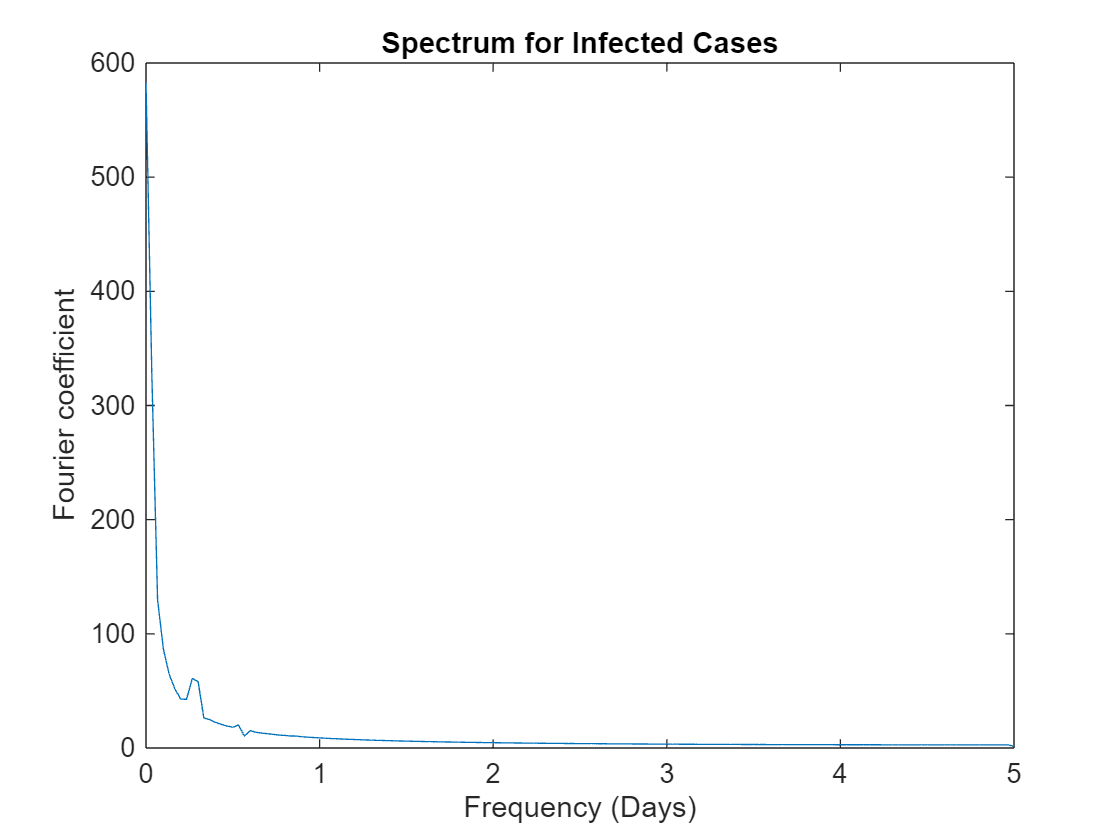

% Define frequency range
N=length(t1)-1;
f = 1/30*(0:length(t1)/2);
% Calculate spectrum
spectrum=fft(S1);
P2 = abs(spectrum/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1)
title('Spectrum for Infected Cases')
xlabel('Frequency (Days)')
ylabel('Fourier coefficient')

This time, there is still a peak at 0 days for the same reason as discussed previously, however the other peak appears at a lower frequency, near 0.3 days. This makes sense as we increased our period of the rate of infection from 1 day to 3 days, which would make the frequency decrease as frequency is inversely proportional to the period. 

## SIR Function

function [time,Svals,Ivals,Rvals] = SIR(B0,A,w)
%SIR SIR Model for Part 4
% Taken from Part 1, modified to use function for B

% Initial Values
I0 = 10;
S0 = 990;
R0 = 0;

Beta = @(t) B0*(1+A*sin(w*t)); %transmission rate
Gamma = 0.1; %Recovery Rate

h = 0.1; %step size
t0 = 0; tf = 30; %time interval
time = t0:h:tf;

BN1=Beta(time)./1000;
    
Rvals = zeros(size(time));
Svals = zeros(size(time));
Ivals = zeros(size(time));
Nvals = zeros(size(time));
    
Rvals(1) = R0;
Svals(1) = S0;
Ivals(1) = I0;
Nvals(1) = 1000;
                 

for i = 1:length(time)-1

    dSdt = @(I,S) -BN1(i)*S*I;
    dIdt = @(I,S) (BN1(i)*S*I)-(Gamma*I);
    dRdt = @(I) Gamma*I; 

    R=Rvals(i);
    S=Svals(i);
    I=Ivals(i);
         
    rk1 = dRdt(I);           % Runge Kutta Recovered K1 
    sk1 = dSdt(I,S);            % Runge Kutta Susceptible K1 
    ik1 = dIdt(I,S);           % Runge Kutta Infected K1
       
    ik2 = dIdt((I + ik1 * (h/2)) , S + sk1 * (h/2));           % Runge Kutta Infected K2
    rk2 = dRdt(I + ik1 * (h/2));           % Runge Kutta Recovered K2 
    sk2 = dSdt(I + ik1 * (h/2)  , (S + sk1 * (h/2)));           % Runge Kutta Susceptible K2
           
    sk3 = dSdt(I + ik2 * (h/2) ,(S + sk2 * (h/2)));            % Runge Kutta Susceptible K3 
    ik3 = dIdt((I + ik2 * (h/2)) ,S + sk2 * (h/2));           % Runge Kutta Infected K3
    rk3 = dRdt(I + ik2 * (h/2));           % Runge Kutta Recovered K3 
         
    ik4 = dIdt((I + ik3 * h),S + sk3 * h);           % Runge Kutta Infected K4
    sk4 = dSdt(I + ik3 * h , (S + sk3 * h));           % Runge Kutta Susceptible K4 
    rk4 = dRdt(I + ik3 * h);
            
    Rvals(i+1) = R + (1/6) * (rk1 + 2*(rk2) + 2*(rk3) + rk4) * h;
    Svals(i+1) = S + (1/6) * (sk1 + 2*(sk2) + 2*(sk3) + sk4) * h;
    Ivals(i+1) = I + (1/6) * (ik1 + 2*(ik2) + 2*(ik3) + ik4) * h;
    Nvals(i+1) = Rvals(i+1) + Svals(i+1) + Ivals(i+1);
end


end